## How does a phone know its orientation?

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

    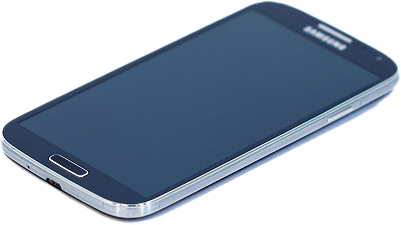

A cell phone contains three devices:

- a **magnetometer** that detects the Earth's magnetic field

- an **accelerometer** that detects linear acceleration 

- a **gyroscope** that detects rotational acceleration

Alone, each sensor does not provide enough information to determine the absolute orientation of the phone. But combine these signals with vector mathematics (in a process known as *sensor fusion*), and you can estimate the absolute orientation. 

In this set of live scripts, you'll learn about vectors and how you can use them to estimate a cell phone's orientation from its sensor readings.

# Vector Basics

  **Pro-tip**: This live script is meant to be used with the code hidden. Select the `VIEW` tab and switch to `Hide Code`.

 **Note:** Your answers should be accurate to at least 3 decimal places. If they are not, they will be marked incorrect.

## 1. Vector definition

A **scalar** quantity is defined by a single numeric value and has no direction. A **vector **quantity, on the other hand, has both **magnitude** and **direction** and is typically defined in terms of several components.

** Exercise. **Several physical quantities are described below. Which of them are vector quantities?

    1. Your age

    2. The velocity of an airplane

      

    3. The magnetic force that directs the needle of a compass north

       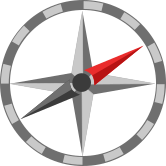

    4. The temperature on the surface of the sun: 5500°C

    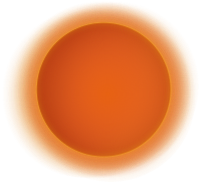

Type a list of which answers are vector quantities in the space below (for example: 1, 3, 4).

vectorQuantities = [0];
gradeVectorQuantities(vectorQuantities)

## **2. Vector visualization**

### 2D vectors

A two-dimensional vector contains two scalar components. 


$$\mathbf{v} = \left[ v_1, v_2]$$


When graphing vectors, the components are visualized as the $x$ and $y$ extension of the vector: $\mathbf{v} = [v_x, v_y]$. The components determine how far the vector $\mathbf{v}$ extends in the direction of the $x$ and $y$ axes.

% Define the vector
v = [2,-4]; % default: v=[2,-4]

% Plot the vector
figure("position",[1 1 350 350])
hold on
setup2DVectorPlot([-5 5 -5 5])
plotVector2DWithComponents(v,"v",1)
hold off

  **Try**

- Use the sliders to set $\mathbf{v} = [-3,-3]
$ and then $\mathbf{v} = [-4,2]
$, and observe the changes to the vector.

- Set $\mathbf{v} = [2,2]
$, how *long* is $\mathbf{v}$? Type your prediction below, and you can check it later.

vLength = 0; % Default: 0

### 3D vectors

A 3D vector has three components


$$\mathbf{v} = \left[ v_x, v_y, v_z]$$


Let's graph a 3D vector.

% Define the vector
v = [2,-4,4]; % default: v=[2,-4,4]

% Plot the vector
axisLims = [-5 5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3DWithComponents(v,"v",1)
hold off
view([110 15])

  **Pro-tip**: You can click and drag the 3D plot to rotate the axes.

  **Try**

- Use the sliders to set $\mathbf{v} = [3,-4,0]
$. What plane does the $\mathbf{v}$ lie in?

- Set $\mathbf{v} = [2,0,2]
$. What angle do you think $\mathbf{v}$ make with the $x$-axis? Write your answer below in degrees. 

axisAngle = 0;
gradeAxisAngle(axisAngle);

 **Reflect**

- Do 4D vectors exist? If so, why aren't they visualized here?

## 3. Vector magnitude

### 2D vectors

The length of the vector is referred to as it’s **magnitude**. The magnitude is typically denoted using two vertical lines: $\Vert \mathbf{v} \Vert$. In two dimensions, you can compute the magnitude using the Pythagorean theorem.

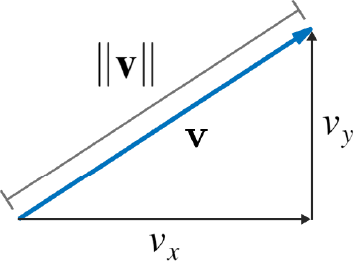

So $\Vert \mathbf{v} \Vert= \sqrt{ {v_x}^2 + {v_y}^2 }$.

** Exercise. **Compute the magnitude of the vector $\mathbf{v} = [3, 4]$ and enter the answer below.

checkMag(0); % default: 0

 **Reflect**

- Add the components of $\mathbf{v}$. Is the answer equal to the magnitude?

** Exercise. **Fill in the expression for magnitude below using MATLAB functions and then observe the plot. 

  **Pro-tip. **Access the elements of $\mathbf{v}$ using indexing as `v(1)` and `v(2)`.  Use `^2` to compute the square and [sqrt](https://www.mathworks.com/help/matlab/ref/sqrt.html) to compute the square root.

% Define the vector
v = [2,3]; % default: v=[2,3]

% Replace with your expression for the magnitude
mag_a = 0; % default NaN
% Plot the vector
figure("position",[1 1 350 350])
hold on
setup2DVectorPlot([-5 5 -5 5])
plotVector2D([0 0],v,"\Vert \mathbf{v} \Vert \approx" + num2str(mag_a,3),-3)
hold off

  **Try**

- Set $\mathbf{v} = [2,2]$. At the start of the lesson, you thought that the length of this $\mathbf{v}$ was:

vLength

            were you right?

### 3D vectors

Consider the plot of a 3-dimensional vector $\mathbf{v}$ and its components.

 
v = [4 5 5];
% Plot the vector
axisLims = [-6.5 6.5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],v,"\mathbf{v}",-1)
plotVector3D([0 0 0],[v(1) 0 0],"\mathbf{v}_x",-2)
plotVector3D([v(1) 0 0],[0 v(2) 0],"\mathbf{v}_y",-2)
plotVector3D([0 0 0],[v(1) v(2) 0],"\mathbf{v}_{x,y}",-2)
plotVector3D([v(1) v(2) 0],[0 0 v(3)],"\mathbf{v}_{z}",1)
hold off
view([110 25])

A single application of the Pythagorean theorem is insufficient to compute $||\mathbf{v}||$. 

** Exercise. **Derive the formula for $||\mathbf{v}||$ in 3D. Enter the expression below using the symbolic MATLAB variables `v_x`, `v_y`, and `v_z`. 

  **Pro-tip. **Symbolic math in MATLAB uses many of the same operators as standard MATLAB: `^2` is used to compute the square and `sqrt()` is used to compute the square root. To learn more about the Symbolic Math Toolbox, you can visit the documentation [here](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html).

syms v_x v_y v_z % Define symbolic variables
magv = 0
checkSymbolicMag(magv)

**Hint:** apply the Pythagorean theorem twice.

 **Exercise. **Compute the magnitude of the vector $\mathbf{u} = [3, 5, -3]$ and type the answer below.

% Type the magnitude of u (must match to at least 3 sig figs)
check3DMag(0)

## 4. Vector direction

Vectors have direction and magnitude. In general, the **direction** of the vector is described by the angle it makes relative to the reference direction. In 2D, you can use the inverse tangent function to compute the angle a vector makes with the $x$-axis.

    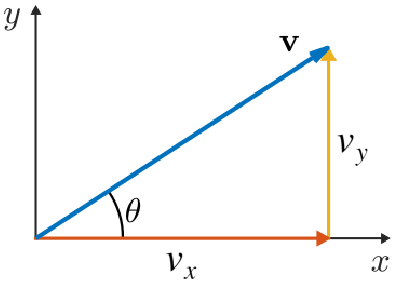

    
$$\theta = \tan^{-1}\left( \frac{v_y}{v_x} \right)$$


** Exercise. **Compute the angle, $\theta$, that $\mathbf{v} = [2, -3]$ makes with the $x$-axis in degrees (include at least 4 decimal places).

  **Pro-tip. **Use the [atand](https://se.mathworks.com/help/matlab/ref/atand.html?s_tid=srchtitle) function to compute the inverse tangent in degrees (`atan` computes it in radians).

theta = 0
checkAngle2D(theta)

The graph below illustrates the angle that a 2D vector makes with the $+x$-axis. 

% Define the vector
v = [2,3]; % default: v=[2,3]

% Plot the vector
figure("position",[1 1 350 350])
hold on
setup2DVectorPlot([-5 5 -5 5])
plotVectorWithAngle([0 0],v) 
hold off

  **Try**

- Set $\mathbf{v} = [-3,-3]$ and note the angle. Then set $\mathbf{v} = [-1,-1]$. Does the orientation change? Does the magnitude change?

## 5. Accelerometer exploration

In this section you will take accelerometer readings, graph them as vectors, and explore their physical meaning. In order to complete this section, you will need to access accelerometer data. There are two options

- Access the accelerometer on your cell phone or tablet using the MATLAB mobile app ([MATLAB Mobile instructions](https://www.mathworks.com/help/matlabmobile/ug/sensor-data-collection-with-matlab-mobile.html)).

- Use the data attached in [AccelerometerReadings.mp4](matlab: OpenOnComputer("AccelerometerReadings.mp4")).

          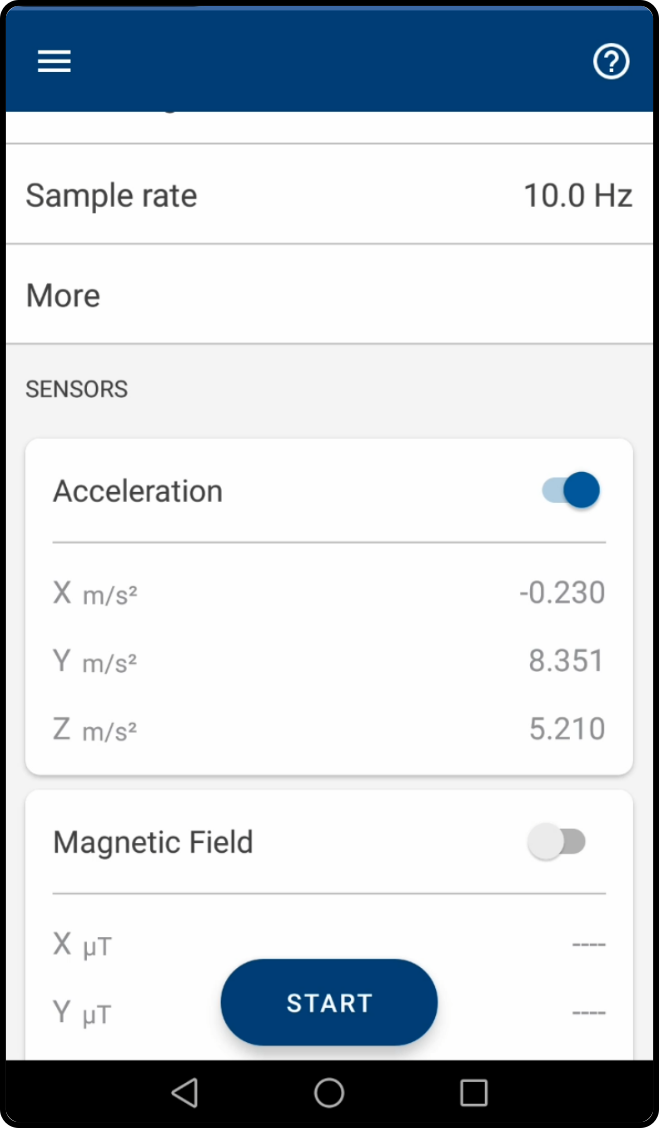

        * An accelerometer reading in the MATLAB Mobile app*

### Part 1

  **Task. **Take accelerometer readings as indicated below.

- Your values should be recorded as a vector $\mathbf{a} = [a_x, a_y, a_z]$. An example reading: `[0.2 5 7.32]`

- Note that even when the phone is still, the values are likely to be randomly shifting due to measurement error. This error is not important for this exercise, so simply select any observed value once the phone is still.

% Record your accelerometer values below 
a = [0 0 0]; % Default: [0 0 0]
b = [0 0 0]; % Default: [0 0 0]
c = [0 0 0]; % Default: [0 0 0]
d = [0 0 0]; % Default: [0 0 0]

% Graph the accelerometer vector
axisLims = [-10 10];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],a,"\mathbf{a}",-2)
plotVector3D([0 0 0],b,"\mathbf{b}",-2)
plotVector3D([0 0 0],c,"\mathbf{c}",-2)
plotVector3D([0 0 0],d,"\mathbf{d}",-2)
hold off
view([110 25])

 **Reflect**

- Based on the vectors that you observe, what information does the accelerometer offer?

- If the phone isn't moving, why is the acceleration vector nonzero?

### Part 2

 **Exercise.** Compute the magnitude of each vector you recorded above.

% Type the answers in the space provided below 
% Note: your answers must match to at least 4 sig figs
mag_a = 0; % Default: 0
mag_b = 0; % Default: 0
mag_c = 0; % Default: 0
mag_d = 0; % Default: 0

checkMagnitudes(a,b,c,d,mag_a,mag_b,mag_c,mag_d);

 **Reflect**

- Does the magnitude of the vector change? If so, what do you think causes the changes to the magnitude?

- What physical quantity does the magnitude represent?

- It is a fact that the physical phenomenon in question does not change direction. Why does the vector change direction?

### Part 3

In 3D, the angle that a vector $\mathbf{v} = [v_x, v_y, v_z]$ makes with the $z$-axis can be computed using

    
$$\theta = \tan^{-1} \left( \frac{\sqrt{v_x^2 + v_y^2} }{v_z} \right)$$


 **Exercise. **Compute the angle that the vectors make with the $z$-axis and enter the answers below. Use at least four decimal places.

% Type the answers in the space provided below 
angle_a = 0; % Default: 0
angle_b = 0; % Default: 0
angle_c = 0; % Default: 0
angle_d = 0; % Default: 0
checkAngles(a,b,c,d,angle_a,angle_b,angle_c,angle_d);

### Part 4

  **Task. **Stand the phone up straight and take another reading. Type the answer as a vector below.

% Record your accelerometer values below 
aUpright = [0 0 0]; % Default: [0 0 0] 

% Graph the accelerometer vector
axisLims = [-10 10];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],a,"\mathbf{a}",-2)
plotVector3D([0 0 0],c,"\mathbf{b}",-2)
plotVector3D([0 0 0],aUpright,"\mathbf{e}",-2)
hold off
view([110 25])

 **Reflect:**

- What is the physical meaning of each vector's orientation?

- What orientation information is **not **captured by the accelerometer?

- There are two other detectors that have not been looked at yet: the magnetometer and the gyroscope. Which of these do you think will help to fill in the missing orientation information?

### 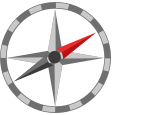**Further exploration**

There are three angles associated with the orientation of the cell phone: the pitch, yaw, and roll. 

            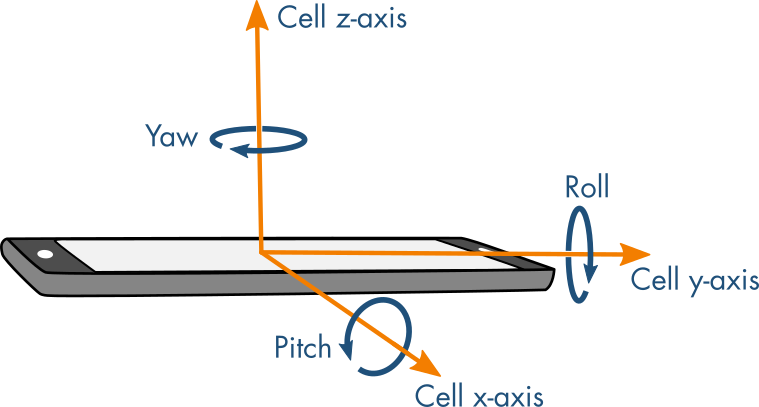

            *Illustration of the cell phone axes and rotation*

As you've seen in this activity, it is possible to capture the tilt of the phone as it rotates about its $x$-axis from lying flat using the accelerometer. This is the pitch. You may have also noticed that the rotation around the phone's $z$-axis (known as the yaw) is not captured when the phone is flat on the table. There's a third orientation: the roll, which involves rotations about the $y$-axis. 

  Try rotating the phone about the $y$-axis from rest on a flat surface to change the roll. Record a few accelerometer readings below. Is the roll captured by the accelerometer?

% Record your accelerometer values below 
u = [0 0 0]; % Default: [0 0 0]
v = [0 0 0]; % Default: [0 0 0]
w = [0 0 0]; % Default: [0 0 0]

% Graph the accelerometer vector
axisLims = [-10 10];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],u,"\mathbf{u}",-2)
plotVector3D([0 0 0],v,"\mathbf{v}",-2)
plotVector3D([0 0 0],w,"\mathbf{w}",-2)
hold off
view([110 25])

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

%% Helper functions
%% These functions are for plotting 2D vectors with their labels.

function setup2DVectorPlot(axisLims) 
% Sets up axes for visualizing 2D vectors
    fs = 14; % font size for graph
    ax = gca;
    ax.XAxisLocation = "origin";
    ax.YAxisLocation = "origin";    
    ax.Position = [0.05 0.05 0.9 0.9];
    axis equal tight
    axis(axisLims)
    box on
    xlabel("$x$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    ax.XTick = round(axisLims(1)):round(axisLims(2));
    ax.XTickLabel = [];
    ax.YTick = round(axisLims(1)):round(axisLims(2));
    ax.YTickLabel = [];
end

% Visualizes a 2D vector with the given name
function plotVector2D(u0,u,name,nameOffset) 
    fs = 14; % font size for the graph
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/sqrt(dot(u,u)),"linewidth",1.5)
    offset = null(u)/3*nameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2),strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

 % Visualizes a 2D vector and display the angle it makes with the x-axis
function plotVectorWithAngle(u0,u)
    fs = 14; % font size for graph
    theta = atan2d(u(2),u(1));
    name = strcat("\theta =", num2str(round(theta),3),"^\circ");
    t = linspace(0,theta);
    x = 1*cosd(t);
    y = 1*sind(t);
    plot(x,y,"k")
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/sqrt(dot(u,u)),"linewidth",1.5)
    text(x(end/2)*2, y(end/2)*2, strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

% Visualizes a 2D vector with its components
function plotVector2DWithComponents(v,name,nameOffset) 
    plotVector2D([0 0],v,strcat("\mathbf{",name,"}"),nameOffset)
    plotVector2D([0 0],[v(1) 0],strcat(name,"_x"),nameOffset)
    plotVector2D([0 0],[0 v(2)],strcat(name,"_y"),nameOffset)  
    plot([0 v(1)],[v(2) v(2)],":","color",[0.9290, 0.6940, 0.1250])
    plot([v(1) v(1)],[0 v(2)],":","color",[0.8500, 0.3250, 0.0980])
end

% Sets up nice axes for visualizing 3D vectors
function plotVector3DAxis(axlims) 
    cla
    fs = 14; % fontsize for graph
    lb = axlims(1);
    ub = axlims(2);
    a = lb;
    b = ub-a;
    buff = b*0.1;
    c = ub+buff/2;
    ca = [0.3 0.3 0.3 0.6];
    axis([a-buff,c+buff,a-buff,c+buff,a-buff,c+buff])
    
    % Plot the axes and labels
    quiver3(a,0,0,b,0,0,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    quiver3(0,a,0,0,b,0,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    quiver3(0,0,a,0,0,b,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    text(c,0,0,"$x$", "Interpreter","latex","fontsize",fs)
    text(0,c,0,"$y$", "Interpreter","latex","fontsize",fs)
    text(0,0,c,"$z$", "Interpreter","latex","fontsize",fs)
    axis equal tight
    set(gca,"Position",[0.05 0.05 0.9 0.9]);
    set(gca,"CameraViewAngleMode","Manual")    
    set(gca,"Color","none","XColor","none","YColor","none","ZColor","none");
    set(gca,"ColorOrderIndex",1)
end


function plotVector3D(u0,u,name,nameOffset)
% Visualize a 3D vector with the given name
    xlims = 0.5*get(gca,"xlim");
    scaleFactor = 0.25*(xlims(2) - xlims(1));
    fs = 14; % font size for graph
    quiver3(u0(1),u0(2),u0(3),u(1),u(2),u(3),"autoscale","off","maxheadsize",scaleFactor/norm(u),"linewidth",1.5)
    offset = null(u)/3*nameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2), u0(3) + u(3)/2 + offset(3), ...
        strcat("$",name,"$"),"Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

function plotVector3DWithComponents(v,name,nameOffset) 
% Visualizes a 3D vector and its components
    plotVector3D([0 0 0],v,strcat("\mathbf{",name,"}"),nameOffset)
    plotVector3D([0 0 0],[v(1) 0 0],strcat(name,"_x"),nameOffset)
    plotVector3D([0 0 0],[0 v(2) 0],strcat(name,"_y"),nameOffset)
    plotVector3D([0 0 0],[0 0 v(3)],strcat(name,"_z"),nameOffset)
    plot3([0 v(1)],[v(2) v(2)], [0 0],":","color",[0.8500 0.3250 0.0980])
    plot3([v(1) v(1)],[0 v(2)], [0 0],":","color",[0.9290 0.6940 0.1250])
    plot3([v(1) v(1)],[v(2) v(2)], [0 v(3)],":","color",[0.4940 0.1840 0.5560])
end

%% These functions check the example answers
function checkAns(val,userVal) 
% Checks the answer of a variable
    if(all( abs( userVal - val ) < 1e-3 ))
        disp("Correct!")
    else
        warning("Incorrect :(")
    end
end

function gradeVectorQuantities(vectorQuantities)
    checkAns(sort(vectorQuantities),[2 3])
end

function gradeAxisAngle(axisAngle)
    checkAns(axisAngle,45)
end

function checkAngle2D(userValue)
    checkAns(abs(userValue),56.30993247)
end

function checkMagnitudes(aLean1,aLean2,aFlat1,aFlat2,magLean1,magLean2,magFlat1,magFlat2)
    checkAns(norm(aLean1),magLean1);
    checkAns(norm(aLean2),magLean2);
    checkAns(norm(aFlat1),magFlat1);
    checkAns(norm(aFlat2),magFlat2);
end

function checkAngles(a,b,c,d,angle_a,angle_b,angle_c,angle_d)
    theta = @(v) atand( sqrt(v(1).^2 + v(2).^2)./v(3));
    checkAns(theta(a),angle_a);
    checkAns(theta(b),angle_b);
    checkAns(theta(c),angle_c);
    checkAns(theta(d),angle_d);
end

function checkMag(userVal) 
    val = 5;
    checkAns(val,userVal);
end

function check3DMag(userVal)
    v = [3 5 -3];
    checkAns(norm(v),userVal)
end

function checkSymbolicMag(userVal)
    syms v_x v_y v_z
    ansValue = sqrt(v_x^2 + v_y^2 + v_z^2);
    if(isequal(userVal,ansValue))
        disp("Correct!")
    else
        warning("Incorrect :(")
    end
end
